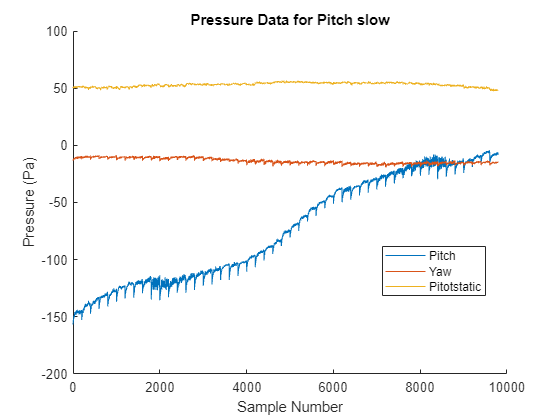

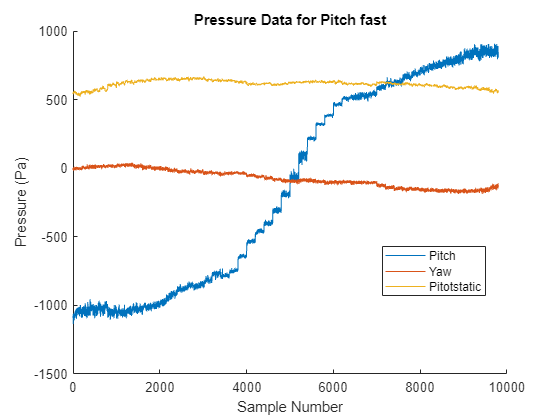

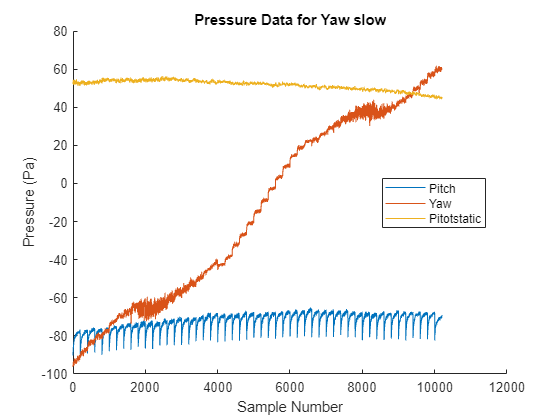

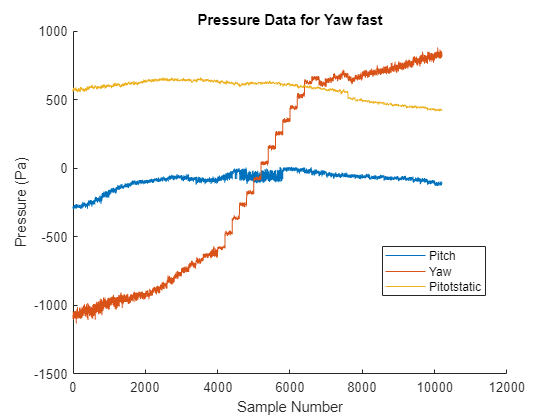

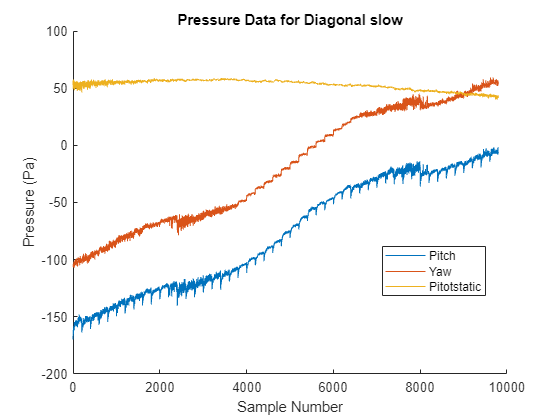

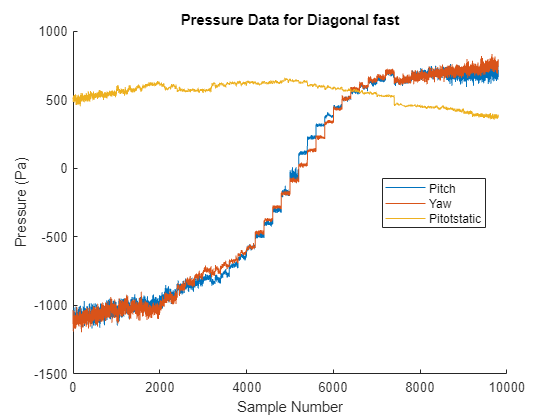

% Define the range of degrees
pitch_degrees = -25:23;
yaw_degrees = -25:25;
diagonal_degrees = -25:23;

% Define the folder names
folder_names = {'Pitch_slow', 'Pitch_fast', 'Yaw_slow', 'Yaw_fast', 'Diagonal_slow', 'Diagonal_fast'};

% Loop through each folder
for j = 1:length(folder_names)
    folder_name = folder_names{j};
    
    % Initialize empty arrays to store pitch, yaw, and Pitotstatic data
    all_pitch_data = [];
    all_yaw_data = [];
    all_pitotstatic_data = [];
    
    % Determine the degrees based on the folder name
    if contains(folder_name, 'Pitch')
        degrees = pitch_degrees;
    elseif contains(folder_name, 'Yaw')
        degrees = yaw_degrees;
    elseif contains(folder_name, 'Diagonal')
        degrees = diagonal_degrees;
    end
    
    % Loop through each degree
    for i = 1:length(degrees)
        % Construct the file name with the relative path
        file_name = fullfile('./data_files/MVP2_20FEB2024_Testing', folder_name, sprintf('%ddeg.csv', degrees(i)));

        % Read the CSV file
        tbl = readtable(file_name); % Read the CSV file into a table

        % Extract pitch, yaw, and Pitotstatic data
        pitch_data = tbl.Pitch; % Assuming 'Pitch' is the column name for pitch data
        yaw_data = tbl.Yaw; % Assuming 'Yaw' is the column name for yaw data
        pitotstatic_data = tbl.Pitotstatic; % Assuming 'Pitotstatic' is the column name for Pitotstatic data

        % Concatenate data to the end of respective arrays
        all_pitch_data = [all_pitch_data; pitch_data];
        all_yaw_data = [all_yaw_data; yaw_data];
        all_pitotstatic_data = [all_pitotstatic_data; pitotstatic_data];
    end

    % Plot all data on the same graph
    figure;
    hold on;
    
    % Plot pitch data
    plot(all_pitch_data, 'DisplayName', 'Pitch');
    
    % Plot yaw data
    plot(all_yaw_data, 'DisplayName', 'Yaw');
    
    % Plot Pitotstatic data
    plot(all_pitotstatic_data, 'DisplayName', 'Pitotstatic');

    % Add labels and legend
    xlabel('Sample Number');
    ylabel('Pressure (Pa)');
    
    % Replace underscore with space in the folder name for the title
    folder_title = strrep(folder_name, '_', ' ');
    title(['Pressure Data for ' folder_title]);
    
    legend('Location', 'best');
    hold off;
end